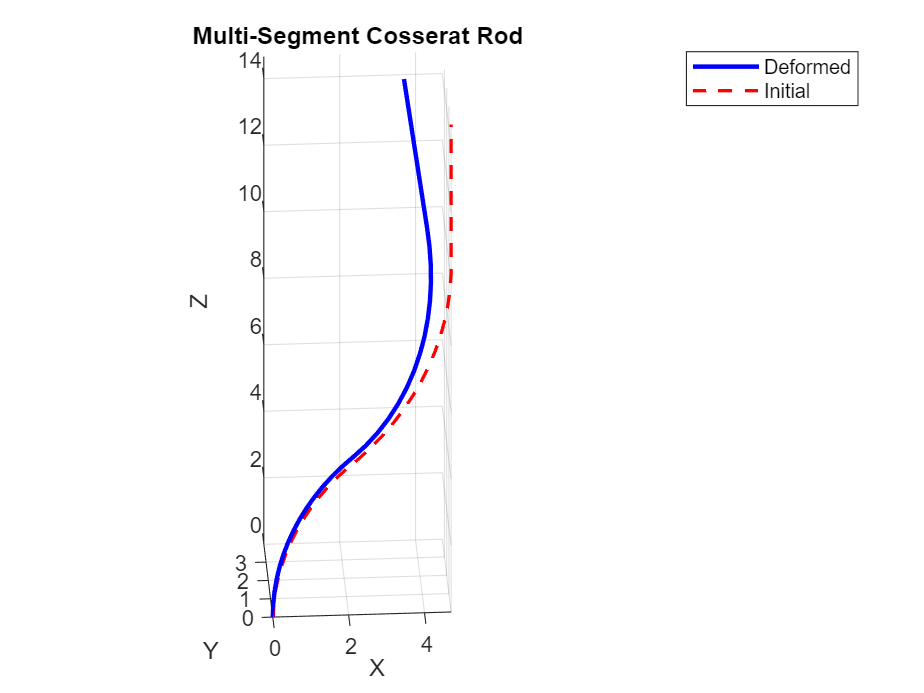

%This is a test file for beam bending simulation

%TODO:
%Implementing distributed force
%Implementing multiple segments

clear, close all

% Parameters
EI = 3;         % Bending stiffness
GJ = .7;
r = 5 / pi;        % Robot radius
n = 1;             % Number of segments
N = 15;         % Number of discretization points
N_d = 2;            % Number of points to estimate distributed force




% Initial actuator positions
act_11_start = [r; 0; 0; 1];
act_12_start = [r*cos(2*pi/3); r*sin(2*pi/3); 0; 1];
act_13_start = [r*cos(4*pi/3); r*sin(4*pi/3); 0; 1];
Base_coord = eye(4);


%Force applied at tip, N
Fx = 0; 
Fy = 0.00; 
Fz = 0.00;

%Moment applied at tip
Mx = 0;
My = 0;
Mz = 0;

%Actuator Lengths
L1 = 4;
L2 = 6;
L3 = 6;
Lck = (L1+L2+L3)/3;

%Turn plot on or off
ploton = false;


simple_f = @(s) [0*s; 0*s; 0*s];  % No dist force
dist_f = @(s) [.01*s; .00*s; -.006*s];  % gravity in -Z
s_force = linspace(0, Lck, N); % same arc length as beam
s_force_d = linspace(0, Lck, N_d);  % force estimation points
%Input function for testing
%[p_def,p_init] = bending_3D(EI,GJ,r,N,L1,L2,L3,act_11_start,act_12_start,act_13_start,Base_coord,.03,0,-.04,Mx,My,Mz,s_force,simple_f,true);
m = 3;          % Number of segments

% ----------------------------
% Segment parameters
% ----------------------------
% L1, L2, L3 are "actuator" lengths for each segment
L1_all = [4, 8,4];   % segment 1 & 2
L2_all = [6, 6,4];
L3_all = [6, 6,4];
L_ck_all = (L1_all+L2_all+L3_all)/3;

% Base coordinates
Base_coord = [0;0;0];

% External forces per segment (global frame)
Fx_all = [0.0, 0,0];
Fy_all = [0, 0.1,0];
Fz_all = [0.0, -.0,0];
Mx_all = [0, 0,0];
My_all = [0, 0,0];
Mz_all = [0, 0,0];

% Distributed force profiles (cell arrays, one per segment)
s_force_all = cell(1,m);
f_dist_vec_all = cell(1,m);
for seg = 1:m
    s_force_all{seg} = linspace(0, L_ck_all(seg), N);
    % Example: constant downward distributed force in z
    f_dist_vec_all{seg} = repmat([0; 0; -0.0], 1, N);
end

% ----------------------------
% Run simulation
% ----------------------------
[p_def_all, p_init_all] = bending_3D_multi( ...
    EI,GJ,r,N, ...
    L1_all,L2_all,L3_all, ...
    Base_coord, ...
    Fx_all,Fy_all,Fz_all, ...
    Mx_all,My_all,Mz_all, ...
    s_force_all,f_dist_vec_all, true);



%For now, I will use the function twice to generate two sets of points for
%two sensed actuator length sets

[p_pred,~] = bending_3D(EI,GJ,r,N,L1,L2,L3,act_11_start,act_12_start,act_13_start,Base_coord,0,0,0,Mx,My,Mz,s_force,simple_f,ploton);

Unrecognized function or variable 'bending_3D'.


[p_act,~] = bending_3D(EI,GJ,r,N,3,6.5,6.5,act_11_start,act_12_start,act_13_start,Base_coord,0,0,0,Mx,My,Mz,s_force,simple_f,ploton);


lambda = .1;                   % regularization weight


% Observed shape
p_target = p_act;

fun = @(x) objective_with_reg_Nd(x, p_target, EI, GJ, r, N, N_d, ...
            L1, L2, L3, act_11_start, act_12_start, act_13_start, ...
            Base_coord, Mx, My, Mz, s_force_d, s_force, lambda);
%Given input xdata and observed output ydata, find x
%x0 = [0; 0; 0];

x0 = 0.0*randn(3*N_d, 1);

lb = -1*ones(3*N_d,1);
ub = 1*ones(3*N_d,1);
% Fix base force components to zero:
lb(1:3) = 0;
ub(1:3) = 0;

options = optimoptions(@lsqnonlin, ...
    'Algorithm', 'trust-region-reflective', ...
    'MaxIterations', 50, ...
    'Display', 'iter-detailed', ...
    'StepTolerance', 1e-4, ...
    'FunctionTolerance', 4e-2, ...
    'FiniteDifferenceType', 'central', ...
    'SpecifyObjectiveGradient', false); 



tic
% Solve

x_est = lsqnonlin(fun, x0, lb, ub, options);
toc



%Post processing
% Forces at the N_d estimation points (3 x N_d)
f_dist_est_d = reshape(x_est, 3, N_d);

% f_dist_est_d = [0 0 0 0 0 0
%                 0 0 0 0 0 0
%                 0 0 0 0 0 0];

% Build full 3xN force matrix with zeros except at nearest N_d nodes
f_dist_est = zeros(3, N);
force_idxs = zeros(1, N_d);


%This is a bit stupid but the other way didnt work
for i = 1:N_d
    [~, force_idxs(i)] = min(abs(s_force - s_force_d(i)));
    f_dist_est(:, force_idxs(i)) = f_dist_est_d(:, i);
end

%f_dist_est(:,1) = [0;0;0]

% Forward solve
[p_act_2, ~] = bending_3D(EI, GJ, r, N, ...
    L1, L2, L3, ...
    act_11_start, act_12_start, act_13_start, ...
    Base_coord, ...
    0, 0, 0, ...
    Mx, My, Mz, ...
    s_force, f_dist_est, ...  
    ploton);

% --- Plot shapes ---
figure
plot3(p_pred(1,:), p_pred(2,:), p_pred(3,:), 'g-', 'LineWidth', 2); hold on;
plot3(p_act(1,:),  p_act(2,:),  p_act(3,:),  'r-', 'LineWidth', 2);
plot3(p_act_2(1,:), p_act_2(2,:), p_act_2(3,:), 'b-', 'LineWidth', 2);

title('Initial (Zero-Force) Curved Shape');

% --- Plotting distributed force arrows at the N_d locations only ---
max_arrow_length = 1;  
mag_nd = vecnorm(f_dist_est_d, 2, 1);             % 1 x N_d
max_force_mag = max(mag_nd) + 1e-9;               % avoid /0
scale_factor = max_arrow_length / max_force_mag;

for j = 1:N_d
    idx = force_idxs(j);                           % nearest backbone node
    pos = p_act_2(:, idx);
    f_vec = f_dist_est_d(:, j);

    f_mag = mag_nd(j);
    if f_mag > 0
        f_dir = f_vec / f_mag;
        L = scale_factor * f_mag;
        quiver3(pos(1), pos(2), pos(3), ...
                L*f_dir(1), L*f_dir(2), L*f_dir(3), ...
                'Color', [0.8 0.3 0.1], ...
                'LineWidth', 1.5, ...
                'MaxHeadSize', 2);
    end
end

xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;
xlim([-6 6]); ylim([-6 6]); zlim([0 8]);
title('3D Backbone Shape from bvp4c');
legend('Predicted Shape','Measured Shape','Shape based on Estimated Force','Estimated Force', ...
       'Location', 'best');
hold off


Functions

function err = objective_with_reg_Nd(x, p_target, EI, GJ, r, N, N_d, ...
                                  L1,L2,L3, act_11_start, act_12_start, act_13_start, ...
                                  Base_coord, Mx, My, Mz, s_force_d, s_force, lambda)

    % Force values only at N_d points
    f_dist_vec_d = reshape(x, 3, N_d);

    % Make a full N-point force array of zeros
    f_dist_vec_full = zeros(3, N);
    
    % Map each of the N_d estimated forces to the nearest s_force index
    for i = 1:N_d
        [~, idx] = min(abs(s_force - s_force_d(i)));
        f_dist_vec_full(:, idx) = f_dist_vec_d(:, i);
    end

    % Pass to bending_3D
    [p_pred, ~] = bending_3D(EI, GJ, r, N, ...
                         L1, L2, L3, ...
                         act_11_start, act_12_start, act_13_start, ...
                         Base_coord, ...
                         0, 0, 0, ...
                         Mx, My, Mz, ...
                         s_force, f_dist_vec_full, false);

    % Residuals
    data_residual = p_pred(:) - p_target(:);

    % Regularization (on the reduced N_d vector)
    f_ddx = f_dist_vec_d(:,1:end-2) - 2*f_dist_vec_d(:,2:end-1) + f_dist_vec_d(:,3:end);
    reg_penalty = lambda * f_ddx(:);

    err = [data_residual; reg_penalty];
end

%Main function, gives deformed shape based on input force/moment and
%initial shape
%% ---------------------------
%% Multi-segment wrapper
%% ---------------------------
%% ---------------------------
%% ---------------------------
%% Multi-segment wrapper (corrected)
%% ---------------------------
function [p_def_all, p_init_all] = bending_3D_multi(EI, GJ, r, N, ...
    L1_all, L2_all, L3_all, ...
    Base_coord, ...
    Fx_all, Fy_all, Fz_all, ...
    Mx_all, My_all, Mz_all, ...
    s_force_all, f_dist_vec_all, ploton)

    m = length(L1_all); % number of segments

    % Base for deformed shape
    p_base = Base_coord(:); 
    R_base = eye(3);

    % Base for initial (force-free) shape
    p_base_init = Base_coord(:);
    R_base_init = eye(3);

    p_def_all = [];
    p_init_all = [];

    for seg = 1:m
        % Extract segment parameters
        L1 = L1_all(seg);
        L2 = L2_all(seg);
        L3 = L3_all(seg);

        Fx = Fx_all(seg);
        Fy = Fy_all(seg);
        Fz = Fz_all(seg);
        Mx = Mx_all(seg);
        My = My_all(seg);
        Mz = Mz_all(seg);

        s_force = s_force_all{seg};
        f_dist_vec = f_dist_vec_all{seg};

        % Call single-segment solver
        [p_def_seg, p_init_seg, R_end] = bending_3D_segment(... 
            EI, GJ, r, N, ...
            L1, L2, L3, ...
            p_base, Fx, Fy, Fz, Mx, My, Mz, ...
            s_force, f_dist_vec, R_base, ...
            p_base_init, R_base_init, ...
            seg==1); % is_first_segment

        % Append while avoiding duplicate connection point
        if seg == 1
            p_def_all  = p_def_seg;
            p_init_all = p_init_seg;
        else
            p_def_all  = [p_def_all,  p_def_seg(:,2:end)];
            p_init_all = [p_init_all, p_init_seg(:,2:end)];
        end

        % Update base for next segment (deformed)
        p_base = p_def_seg(:,end);
        R_base = R_end;

        % Update base for next segment (initial shape)
        p_base_init = p_init_seg(:,end);
        R_base_init = R_init_end(p_init_seg, R_base_init);
    end

    if ploton
        figure;
        plot3(p_def_all(1,:), p_def_all(2,:), p_def_all(3,:), 'b-', 'LineWidth', 2); hold on;
        plot3(p_init_all(1,:), p_init_all(2,:), p_init_all(3,:), 'r--', 'LineWidth', 1.5);
        axis equal; grid on; xlabel('X'); ylabel('Y'); zlabel('Z');
        legend('Deformed','Initial'); title('Multi-Segment Cosserat Rod');
    end
end


%% ---------------------------
%% Helper to extract final rotation from p_init segment
%% ---------------------------
function R_end_init = R_init_end(p_init_seg, R_base_init)
    % Approximate tangent at last segment node
    t_end = p_init_seg(:,end) - p_init_seg(:,end-1);
    t_end = t_end / norm(t_end);

    % Construct new frame aligned with tangent
    z_axis = t_end;

    % pick an x-axis roughly orthogonal to tangent
    x_axis = [1;0;0];
    if abs(dot(x_axis, z_axis)) > 0.99
        x_axis = [0;1;0];
    end

    y_axis = cross(z_axis, x_axis);
    y_axis = y_axis / norm(y_axis);
    x_axis = cross(y_axis, z_axis);

    R_end_init = [x_axis, y_axis, z_axis];
end






%% ---------------------------
%% Single-segment solver (drop-in)
%% ---------------------------
function [p_def, p_init, R_end] = bending_3D_segment(EI, GJ, r, N, ...
    L1, L2, L3, ...
    p_base, Fx, Fy, Fz, Mx, My, Mz, ...
    s_force, f_dist_vec, R_base, ...
    p_base_init, R_base_init, is_first_segment)

    % --- intrinsic geometry ---
    [~, ~, Lck, beta, theta] = gen_transform_2(L1, L2, L3, r, []);
    s_vals = linspace(0, Lck, N);

    % Distributed force interpolation
    if isa(f_dist_vec,'function_handle')
        distributed_force_fun = f_dist_vec;
    elseif ~isempty(f_dist_vec) && ~isempty(s_force)
        distributed_force_fun = @(s) interp1(s_force, f_dist_vec', s, 'linear', 'extrap')';
    else
        distributed_force_fun = @(s) [0;0;0];
    end

    % Intrinsic curvature vector
    curvature_magnitude = beta / Lck;
    theta_init = theta * ones(size(s_vals));
    kappa0_vals = [ ...
        curvature_magnitude * cos(theta_init-pi/2);
        curvature_magnitude * sin(theta_init-pi/2);
        zeros(1, length(s_vals))];

    % Parameters for BVP
    params.Kb = EI*eye(3);
    params.Kt = GJ;
    params.Fext = [Fx;Fy;Fz];
    params.Mext = [Mx;My;Mz];
    params.p_base = p_base;
    params.R_base = R_base;
    params.kappa0_fun = @(s) interp1(s_vals',kappa0_vals',s,'linear','extrap')';
    params.n_tip = params.Fext;
    params.m_tip = params.Mext;
    params.distributed_force_fun = distributed_force_fun;

    % Initialize p_init and R_init (force-free)
    p_init = zeros(3,N);
    R_init = zeros(3,3,N);
    p_init(:,1) = p_base_init(:);
    R_init(:,:,1) = R_base_init;

    for i = 2:N
        ds = s_vals(i)-s_vals(i-1);
        kappa_prev = params.kappa0_fun(s_vals(i-1));

        ang = norm(kappa_prev)*ds;
        if ang < 1e-12
            R_step = eye(3) + skew(kappa_prev*ds);
        else
            u = kappa_prev/(norm(kappa_prev)+eps);
            Khat = skew(u);
            R_step = eye(3) + sin(ang)*Khat + (1-cos(ang))*(Khat*Khat);
        end

        R_init(:,:,i) = R_init(:,:,i-1) * R_step;
        t_global = R_init(:,3,i);
        p_init(:,i) = p_init(:,i-1) + t_global*ds;
    end

    % --- Solve BVP ---
    solinit = bvpinit(s_vals,@(s) cosserat_rod_guess(s,params));
    sol = bvp4c(@(s,y) cosserat_rod_ode(s,y,params), ...
                @(ya,yb) cosserat_rod_bc(ya,yb,params,is_first_segment), solinit);
    y_sol = deval(sol,s_vals);

    p_def = y_sol(1:3,:);
    R_end = reshape(y_sol(4:12,end),3,3);
end




%% ---------------------------
%% Cosserat ODE (global-state convention)
%% y = [p(1:3); R(:); n(13:15); m(16:18)]
%% ---------------------------
function dy = cosserat_rod_ode(s, y, params)
    Kb = params.Kb;

    % unpack state
    p = y(1:3);
    R = reshape(y(4:12), 3, 3);
    n = y(13:15);
    m = y(16:18);

    % tangent in global frame: third column of R
    t = R(:,3);

    % intrinsic curvature in body frame
    kappa0 = params.kappa0_fun(s);

    % constitutive: m = Kb*(kappa - kappa0)  =>  kappa = kappa0 + inv(Kb)*m
    kappa = kappa0 + (Kb \ m);

    % kinematics
    dp_ds = t;
    dR_ds = R * skew(kappa);

    % distributed force (global)
    f_dist = params.distributed_force_fun(s);

    % statics (global)
    dn_ds = f_dist;
    dm_ds = -cross(t, n);

    % pack derivatives
    dy = zeros(18,1);
    dy(1:3)    = dp_ds;
    dy(4:12)   = reshape(dR_ds, 9, 1);
    dy(13:15)  = dn_ds;
    dy(16:18)  = dm_ds;
end

%% ---------------------------
%% Boundary conditions for BVP
%% ---------------------------
function res = cosserat_rod_bc(ya, yb, params, is_first_segment)
    n_tip = params.n_tip;
    m_tip = params.m_tip;

    res = zeros(18,1);

    if is_first_segment
        % Fully fixed base
        res(1:3)  = ya(1:3) - params.p_base;
        res(4:12) = ya(4:12) - reshape(params.R_base,9,1);
    else
        % Base continuity: match previous segment's tip
        res(1:3)  = ya(1:3) - params.p_base;        % position continuity
        res(4:12) = ya(4:12) - reshape(params.R_base,9,1); % rotation continuity
    end

    % Tip constraints
    res(13:15) = yb(13:15) - n_tip;
    res(16:18) = yb(16:18) - m_tip;
end




%% ---------------------------
%% Initial guess for BVP (anchored to base)
%% ---------------------------
function yinit = cosserat_rod_guess(s, params)
    % Simple straight-line guess aligned with R_base
    p_guess = params.p_base + params.R_base * [0;0;1] * s;
    R_guess = params.R_base;
    n_guess = params.n_tip;
    m_guess = params.m_tip;

    yinit = [p_guess; reshape(R_guess,9,1); n_guess; m_guess];
end

%% ---------------------------
%% Kinematic transform from actuator lengths
%% (kept consistent with your original implementation)
%% ---------------------------
function [T_k, rho_k,L_ck,beta_k,theta_k] = ...
    gen_transform_2(L_k1, L_k2, L_k3, r, T_prev)

    % Compute average length
    L_ck = (L_k1 + L_k2 + L_k3)/3;

    % Compute bending magnitude (beta)
    beta_k = 2*sqrt(L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3)/(3*r);

    % Compute azimuth angle theta based on actuator differences
    % This ensures the bending direction points along the resultant of actuators
    x = L_k1 - (L_k2 + L_k3)/2;
    y = (sqrt(3)/2)*(L_k2 - L_k3);
    theta_k = atan2(y, x);  % angle in XY plane

    % Curvature per unit length
    rho_k = beta_k / L_ck;

    % Precompute trig terms
    ct = cos(theta_k); st = sin(theta_k);
    cb = cos(beta_k); sb = sin(beta_k);

    % Rotation matrix from local to previous frame
    R_k = [
        cb*ct^2 + st^2,      (cb-1)*ct*st,       ct*sb;
        (cb-1)*ct*st,        ct^2 + cb*st^2,     st*sb;
        -ct*sb,              -st*sb,             cb
    ];

    % Position along previous frame
    if abs(rho_k) < 1e-12
        P_k = [0;0;L_ck];
        T_k = [eye(3) P_k; 0 0 0 1];
    else
        P_k = (1/rho_k) * [(1-cb)*ct; (1-cb)*st; sb];
        T_k = [R_k P_k; 0 0 0 1];
    end
end


%% ---------------------------
%% Skew (hat) operator
%% ---------------------------
function S = skew(v)
    S = [   0   -v(3)  v(2);
          v(3)    0   -v(1);
         -v(2)  v(1)    0 ];
end
